# S1

s1_DC(:,1) = [-3.8:0.2:0];

s1_dc(:,1) = DC_from_XACF('s1_xacf20/conf%d_xacf_1.xvg',20);

s1_dc(:,2) = DC_from_XACF('s1_xacf20/conf%d_xacf_2.xvg',20);

s1_dc(:,3) = DC_from_XACF('s1_xacf20/conf%d_xacf_3.xvg',20);

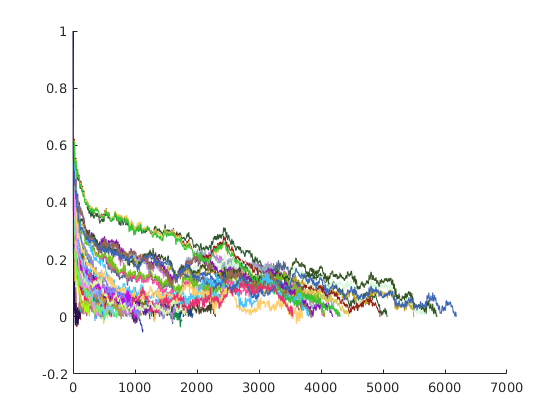

s1_dc(:,4) = DC_from_XACF('s1_xacf20/conf%d_xacf_4.xvg',20);

s1_dc = circshift(s1_dc,1)

s1_dc =     0.0016    0.0015    0.0017    0.0016
    0.0010    0.0011    0.0009    0.0007
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0002    0.0000
    0.0001    0.0001    0.0001    0.0003
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000


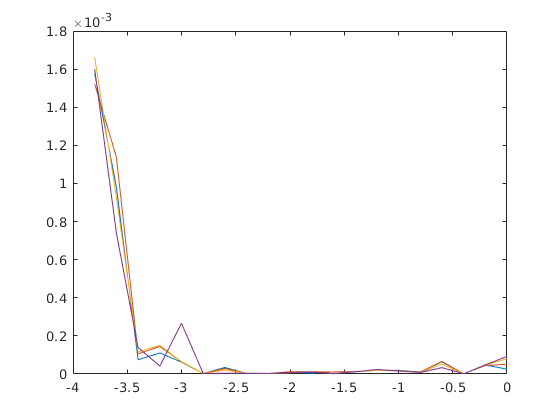

plot(s1_DC(:,1),s1_dc)

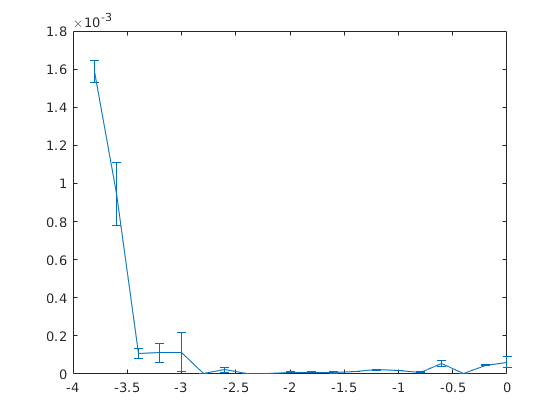

s1_DC(:,2) = mean(s1_dc,2);
s1_DC(:,3) = std(s1_dc,[],2); %/sqrt(size(s1_dc,2));
errorbar(s1_DC(:,1),s1_DC(:,2),s1_DC(:,3))

out = s1_DC;
in = s1_DC ;
in(in(:,1) > 0, :) = [];
out(out(:,1) > 0, :) = [];
in(:,1) = abs(in(:,1));
in = flip(in);
in(1,:) = [];
S1_DC = [out;in];
save S1_DC.mat S1_DC;
csvwrite('S1_DC.csv', S1_DC)

## S2

s2_DC(:,1) = [-1.6:0.2:1.4] - 1;

s2_dc(:,1) = DC_from_XACF('s2_xacf20/conf%d_xacf_1.xvg',16);

s2_dc(:,2) = DC_from_XACF('s2_xacf20/conf%d_xacf_2.xvg',16);

s2_dc(:,3) = DC_from_XACF('s2_xacf20/conf%d_xacf_3.xvg',16);

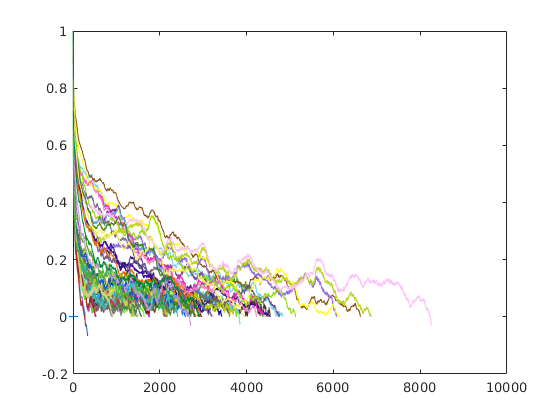

s2_dc(:,4) = DC_from_XACF('s2_xacf20/conf%d_xacf_4.xvg',16);

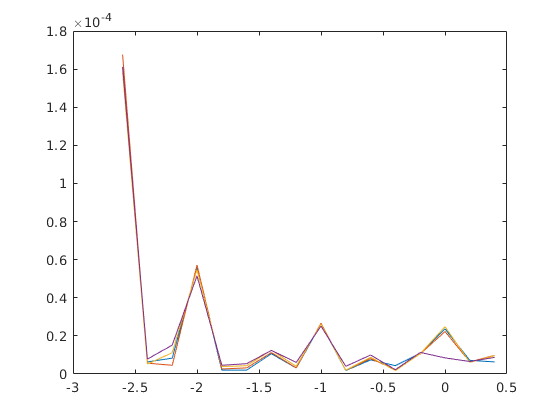

%s2_dc = circshift(s2_dc,1)
plot(s2_DC(:,1),s2_dc)

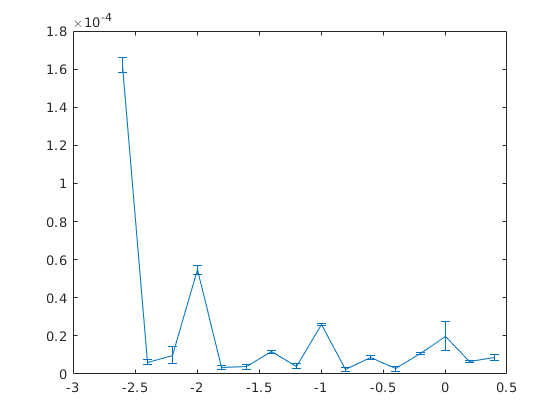

s2_DC(:,2) = mean(s2_dc,2);
s2_DC(:,3) = std(s2_dc,[],2); %/sqrt(size(s2_dc,2));
errorbar(s2_DC(:,1),s2_DC(:,2),s2_DC(:,3))

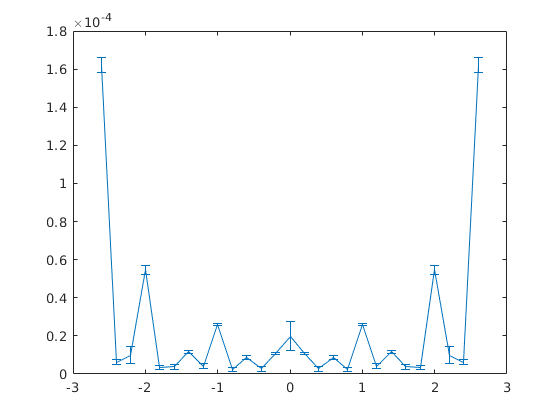

out = s2_DC;
in = s2_DC ;
in(in(:,1) > 0, :) = [];
out(out(:,1) > 0, :) = [];
in(:,1) = abs(in(:,1));
in = flip(in);
in(1,:) = [];
S2_DC = [out;in];
save S2_DC.mat S2_DC;
csvwrite('S2_DC.csv', S2_DC)
errorbar(S2_DC(:,1),S2_DC(:,2),S2_DC(:,3))